# Count Objects using Color Segmentation

In this workshop, we will count the number of objects using color segmentation. 

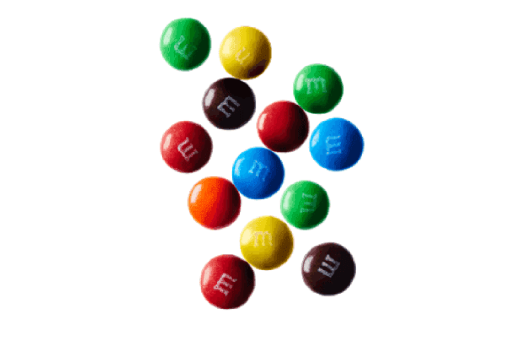

clear;
close all;
clc;

% Load image
img = imread('objects1.png');
figure,
imshow(img);

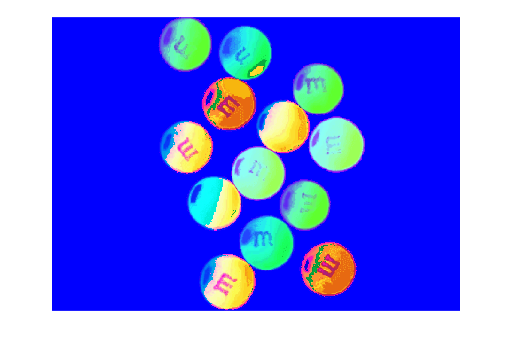


% Convert image to HSV color space
hsvImg = rgb2hsv(img);
figure,
imshow(hsvImg);

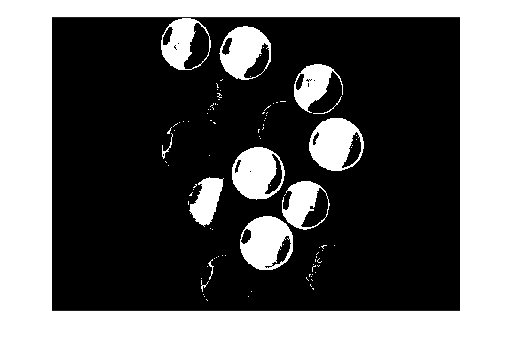


% Define color ranges for objects of interest
colorRanges = {[0, 0.15; 0.8, 1; 0.6, 1], ... % red
               [0.5, 0.7; 0.4, 1; 0.4, 1], ... % orange
               [0.1, 0.2; 0.4, 1; 0.4, 1], ... % yellow
               [0.2, 0.5; 0.4, 1; 0.4, 1], ... % green
               [0.5, 0.7; 0.4, 1; 0.4, 1], ... % blue
               [0, 0.1; 0.5, 0.6; 0.0, 1]}; ... % brown

% Create masks for each object of interest
colorMasks = cell(1, length(colorRanges));
for i = 1:length(colorRanges)
    colorMasks{i} = createColorMask(hsvImg, colorRanges{i});
end

% Combine masks into a single binary image
binaryImg = cat(3, colorMasks{:});
binaryImg = any(binaryImg,3);
figure,
imshow(binaryImg);

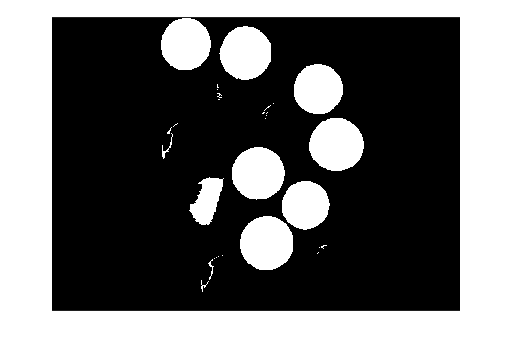


% Remove small objects from binary image
binaryImg = bwareaopen(binaryImg, 40);

% Fill the holes to make a solid object
BW2 = imfill(binaryImg,'holes');
figure,
imshow(BW2);

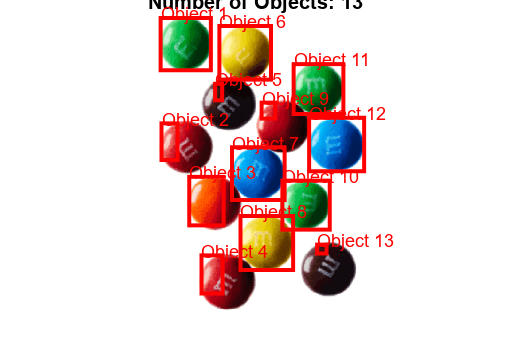


% Count objects in binary image and get their properties
props = regionprops(binaryImg, 'BoundingBox');

% Display original image with red bounding boxes around counted objects
figure;
imshow(img);
hold on;
for i = 1:length(props)
    bb = props(i).BoundingBox;
    rectangle('Position', bb, 'EdgeColor', 'r', 'LineWidth', 2);
    label = ['Object ', num2str(i)];
    text(bb(1), bb(2)-10, label, 'Color', 'r', 'FontSize', 9);
end
hold off;

% Display binary image with number of objects in title
numObjects = length(props);
title(['Number of Objects: ', num2str(numObjects)]);


% Function to create color mask for a given color range
function mask = createColorMask(img, colorRange)
    hueMask = (img(:,:,1) >= colorRange(1,1)) & (img(:,:,1) <= colorRange(1,2));
    satMask = (img(:,:,2) >= colorRange(2,1)) & (img(:,:,2) <= colorRange(2,2));
    valMask = (img(:,:,3) >= colorRange(3,1)) & (img(:,:,3) <= colorRange(3,2));
    mask = hueMask & satMask & valMask;
end